M = readmatrix('natural_freq_meas.txt');

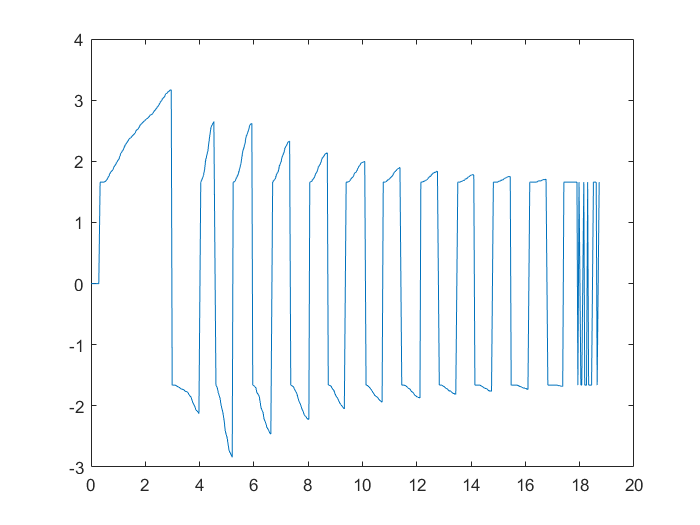

time = M(:,1)-M(1,1);
angle = M(:,2);

plot(time,angle)

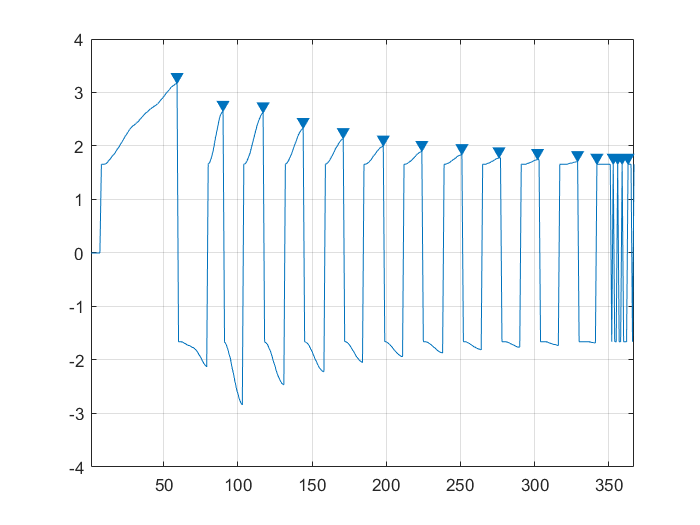

findpeaks(angle) % pretty plot :)

[pks,locs] = findpeaks(angle);

pk_times = locs;
for i = 1:length(locs)
    pk_times(i,1) = time(locs(i,1));
end
pk_times

pk_times =     2.9560
    4.5250
    5.9240
    7.3160
    8.7040
   10.0820
   11.3790
   12.7600
   14.0320
   15.3660


omega_n = mean(diff(pk_times(1:end)))

omega_n = 1.0367



% calculate natural frequency
g = 9.8; % m/s^2

l = g/(omega_n^2)

l = 9.1190